alpha = 2;         
stopband_attenuation = 40; 
Fs = 720;            
Fp = 10;             
Fstop = 20;          

Wc = 2 * Fp / Fs;
Ws = 2 * Fstop / Fs;

% Determine filter order (N) using the formula for Chebyshev Type I filter
[n, Wn] = cheb1ord(Wc, Ws, alpha, stopband_attenuation);

% Design the Chebyshev Type I filter
[z, p] = cheby1(n, alpha, Wn);
sos_chebyshev = tf(z, p, 1/Fs);

% Design the Butterworth filter
[n_butterworth, Wn_butterworth] = buttord(Wc, Ws, alpha, stopband_attenuation);
[z_butterworth, p_butterworth] = butter(n_butterworth, Wn_butterworth);
sos_butterworth = tf(z_butterworth, p_butterworth, 1/Fs);

% Compare the filter orders
fprintf('Chebyshev Type I Filter Order: %d\n', n);

Chebyshev Type I Filter Order: 5


fprintf('Butterworth Filter Order: %d\n', n_butterworth);

Butterworth Filter Order: 8


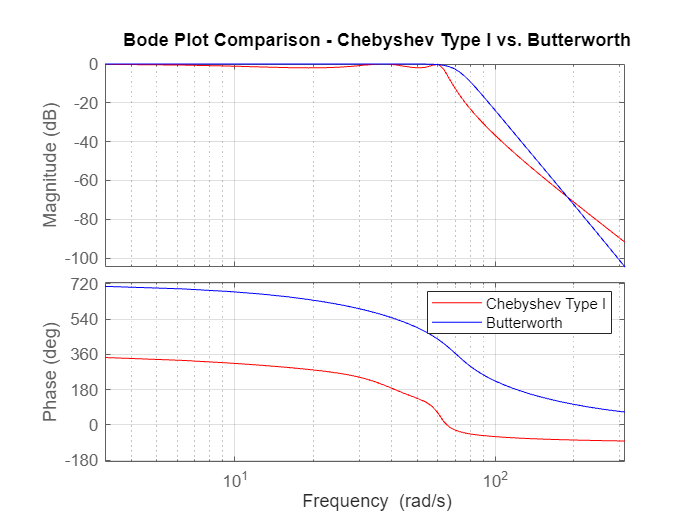


figure;
f=linspace(0,50,100);
bode(sos_chebyshev, 'r', sos_butterworth, 'b', 2*pi*f);
title('Bode Plot Comparison - Chebyshev Type I vs. Butterworth');
legend('Chebyshev Type I', 'Butterworth');
grid on; 


t = 0:1/Fs:1;

impulse_response_chebyshev = impulse(sos_chebyshev, t);
step_response_chebyshev = step(sos_chebyshev, t);

impulse_response_butterworth = impulse(sos_butterworth, t);
step_response_butterworth = step(sos_butterworth, t);

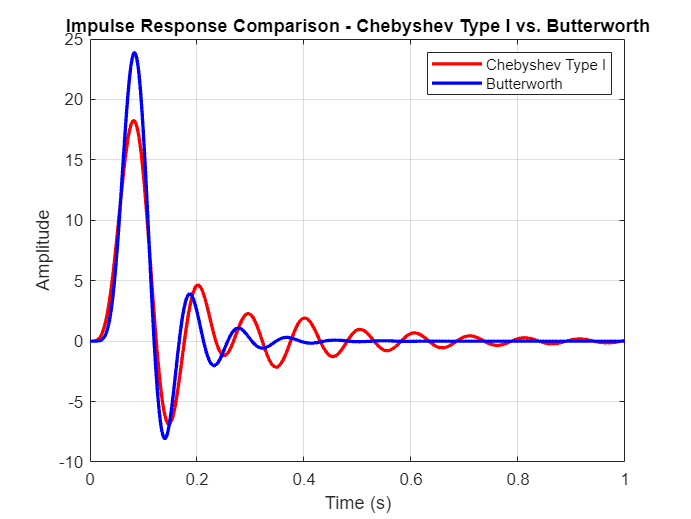


figure;
plot(t, impulse_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, impulse_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Impulse Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'northeast');
grid on;

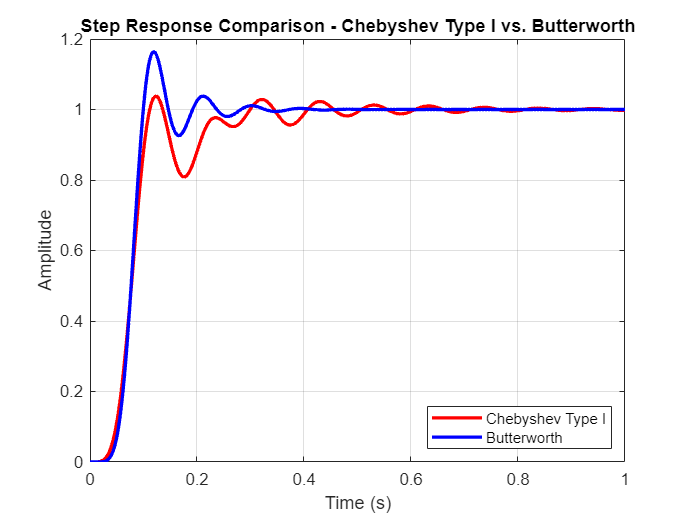


figure;
plot(t, step_response_chebyshev, 'r', 'LineWidth', 2, 'DisplayName', 'Chebyshev Type I');
hold on;
plot(t, step_response_butterworth, 'b', 'LineWidth', 2, 'DisplayName', 'Butterworth');
xlabel('Time (s)');
ylabel('Amplitude');
title('Step Response Comparison - Chebyshev Type I vs. Butterworth');
legend('Location', 'southeast');
grid on;